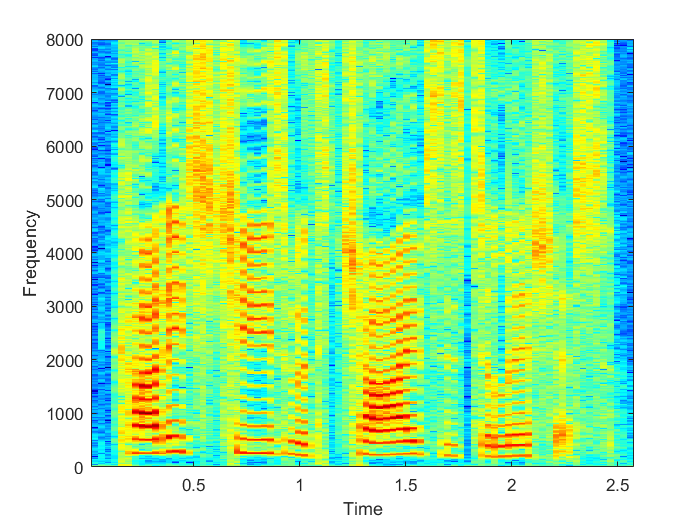

% This is the main program that calls the feature functions,
% does the threshold
% smoothing with a median filter
% and 
%**********************************************************************
%read in audio
[data,fs] = audioread('../data/sf1_cln.wav');

t = [0 : 1/fs : length(data)/fs]; % time in sec
t = t(1:end - 1);

%listen to the sound
% sound(data,fs);

%observe spectogram
specgram(data,1024,fs);


%remove dc component
data = data - mean(data);

%normalize data 
data = data / abs(max(data));

% %pre-emphasis filter 
emph_data = preEmphasis(data);
% specgram(emph_data,1024,fs);

%frame and window- function created
frame_length = 0.025; %play with value;
frame_overlap = 0; % 
[windows,frames,w_FFTS] = framing(data,fs,frame_length,frame_overlap); %between 20 to 30 ms;

[sizeOfFrame,numOfFrames] =  size(frames);

%**********************************************************************
%% FEATURES
%**********************************************************************

%TIME DOMAIN
%**********************************************************************
% 1. ZCR
[ZCR,zcr_wave] = zerocross(frames');

% 2. STE
[ste,ste_wave] = STE(windows');

% 3. autocorrelation
[stacf,stacf_wave] = STACF(windows',5); 

%FREQUENCY DOMAIN
%**********************************************************************
% 4. Entropy
[entropy, entropy_wave] = getEntropy(w_FFTS');

t1 = [0 : 1/fs : length(ste_wave)/fs];
t1 = t1(1:end - 1);

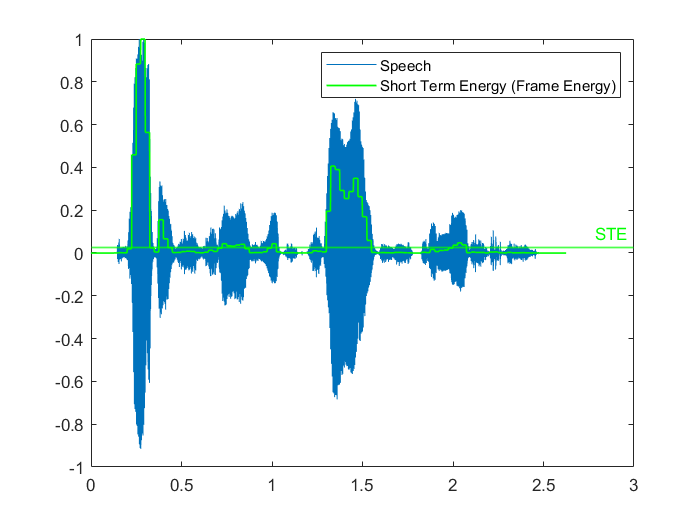

%**********************************************************************
%% DYNAMIC THRESHOLD
%**********************************************************************
bin = floor(numOfFrames/10); %play with value
W = 5; %play with value

%threshold
STE_Thres = dynamicThres(ste,bin,W);
entropy_Thres = dynamicThres(entropy,bin,W);
ZCR_Thres = dynamicThres(ZCR,bin,W);
STACF_Thres = dynamicThres(stacf,bin,W);

plot(t,data'); hold on;
plot(t1,ste_wave,'g','LineWidth',1);
yline(STE_Thres(1),'g','STE','LineWidth',1)
hold off;legend('Speech','Short Term Energy (Frame Energy)');

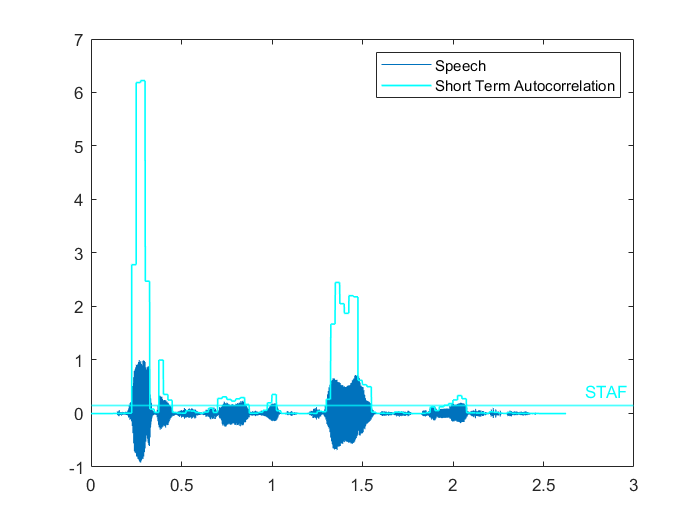

plot(t,data'); hold on;
plot(t1,stacf_wave,'c','LineWidth',1);
yline(STACF_Thres(1),'c','STAF','LineWidth',1)
hold off;legend('Speech','Short Term Autocorrelation');

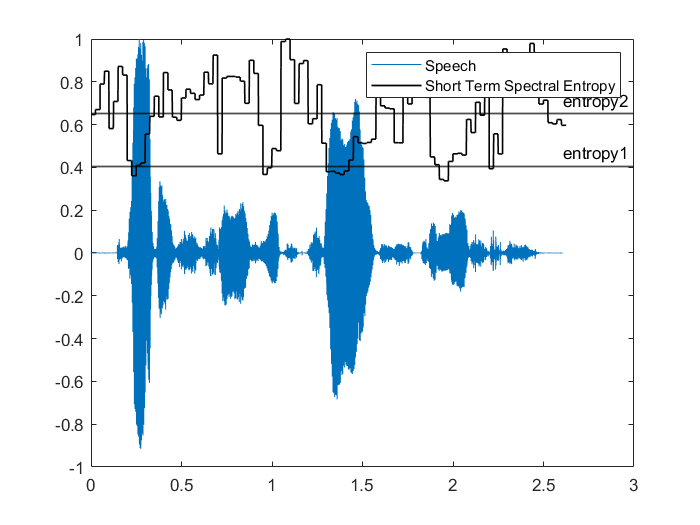


plot(t,data'); hold on;
plot(t1,entropy_wave,'k','LineWidth',1);
yline(entropy_Thres,'k','entropy1','LineWidth',1);
yline(0.65,'k','entropy2','LineWidth',1);hold off;
legend('Speech','Short Term Spectral Entropy');

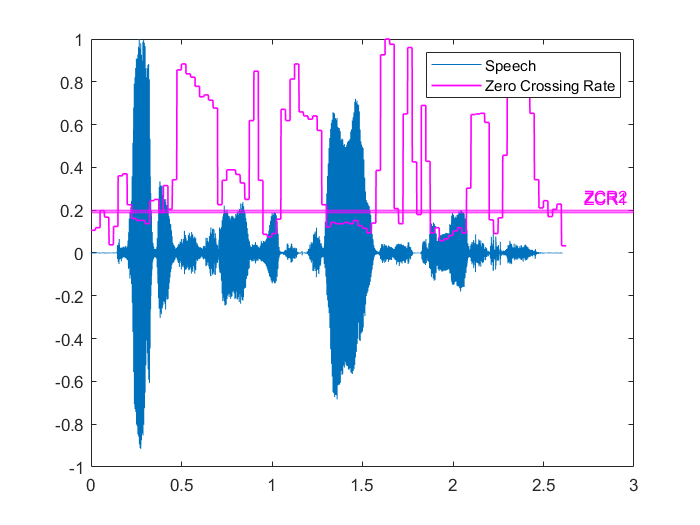

plot(t,data'); hold on;
plot(t1,zcr_wave,'m','LineWidth',1);
yline(ZCR_Thres,'m','ZCR1','LineWidth',1);
yline(0.2,'m','ZCR2','LineWidth',1);hold off;
legend('Speech','Zero Crossing Rate');

%**********************************************************************
%% Finding index of voiced regions
%**********************************************************************

%find points in feature with points above thres
ste_index = find(ste_wave >= STE_Thres(1));
entropy_index = find(entropy <= entropy_Thres);
zcr_index = find(ZCR <= ZCR_Thres);%has a potential issue;

%TODO: come up with a way to use all the above to come up with an ideal

% data_manual = using the 
data_p = zeros(length(data),1);

data_p(ste_index) = 1;

% just change the index
